# Using BIDS formatted data for group analysis using EEGLAB STUDY - Wakeman-Henson data

This tutorial Live Script introduces how to use [LIMO EEG](https://limo-eeg-toolbox.github.io/limo_meeg/index.html) together with [EEGLAB STUDY tool ](https://sccn.github.io/tutorials/10_Group_analysis/)for group analysis. It also demonstrates how to import data organized according to the[ Brain Imaging Data Structure](https://bids.neuroimaging.io/) (BIDS) within EEGLAB (see also the specific reference for [EEG-BIDS](https://www.nature.com/articles/s41597-019-0104-8)). 

## Description of the data

The data used in this tutorial come from [Wakeman adn Henson (2015)](https://www.nature.com/articles/sdata20151).  In this experiment, MEG-EEG data were collected while subjects  viewed famous, unfamiliar and scrambled faces. Each image was repeated  twice (immediately in 50% of cases and 5–10 stimuli apart for the other  50%) and subjects pressed one of two keys with their left or right index finger indicating how symmetric they regarded each image relative to  the average.

The figure below shows details of the paradigm:

                                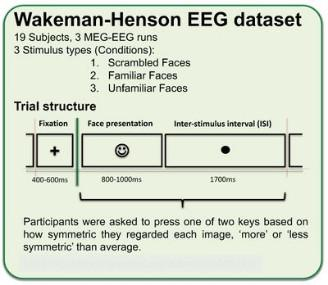

## EEG-BIDS 

The data are organized according to the [BIDS format](https://bids.neuroimaging.io/). You can read more on the specificities of the EEG-BIDS format [here](https://www.nature.com/articles/s41597-019-0104-8). EEGLAB  has dedicated [BIDS tools called bids-matlab-tools](https://github.com/sccn/bids-matlab-tools) to create files, export and import BIDS dataset. This is available  using the EEGLAB plugin manager and must be installed before running the code below. It is worthwhile spending a bit of time looking at how files are organized and named in BIDS, as we will follow this convention throughout.

To know more about how EEGLAB interacts with BIDS file you can also watch this serie of short YouTube videos [here](https://www.youtube.com/playlist?list=PLXc9qfVbMMN3II4EnVQNjOeVl-UprWlnM).

## Download the data

The data were prepared (i.e. EEG extracted, timing corrected,  electrode position re-oriented, event recorded) by Dung Truong, Ramon  Martinez & Arnaud Delorme and can be downloaded from [OpenNeuro 10.18112/openneuro.ds002718.v1.0.3](https://openneuro.org/datasets/ds002718/versions/1.0.3).

Save the data in the "sample_data" subfolder of the EEGLAB release you will be using. 

## Data pre-processing pipeline

Once you have downloaded the data you can run the code below. 

### Start EEGLAB 

clear
[ALLEEG, EEG, CURRENTSET, ALLCOM] = eeglab;
eeglabPath = fileparts(which('eeglab'));

If you saved the data elsewhere than in the EEGLAB "sample_data" subfolder you will have to adjust the filepath variable in the cell below :

filepath = fullfile(eeglabPath, sample_data, 'WakemanHenson_Faces', filesep, 'eeg');

### Import BIDS data

The function pop_importbids() imports a BIDS format folder structure into an EEGLAB study. 

If 'bidsevent' is 'on' then events will be imported from the BIDS .tsv event file and events in the raw binary EEG files will be ignored. Similarly 'bidschanloc', 'on' will import channel locations from BIDS .tsv file and ignore any locations in raw EEG files. The 'studyName' field let you specify the name of the newly created STUDY.

[STUDY, ALLEEG] = pop_importbids(filepath, 'bidsevent','on','bidschanloc','on', ...
    'studyName','Face_detection');

ALLEEG = pop_select( ALLEEG, 'nochannel',{'EEG061','EEG062','EEG063','EEG064'});
CURRENTSTUDY = 1; EEG = ALLEEG; CURRENTSET = [1:length(EEG)];

### Remove bad channels

Here we are using the pop_clean_rawdata() function to remove flat line channels and channels with abnormal activity.

The pop_clean_rawdata()  uses the [Artefact Subspace Reconstruction (ASR)](https://sccn.github.io/tutorials/ConceptsGuide/ASR_background.html) module that is integrated into the EEGLAB [clean_rawdata()](https://github.com/sccn/clean_rawdata) plugin (already installed by default). 

In a further step below we will again use ASR but to remove portions of data. 

EEG = pop_clean_rawdata( EEG,'FlatlineCriterion',5,'ChannelCriterion',0.8,...
    'LineNoiseCriterion',4,'Highpass',[0.25 0.75] ,...
    'BurstCriterion','off','WindowCriterion','off','BurstRejection','off',...
    'Distance','Euclidian','WindowCriterionTolerances','off' );

Error using  ' 
Transpose on ND array is not defined. Use PERMUTE instead.

Error in clean_drifts (line 49)
signal.data = signal.data';

Error in clean_artifacts (line 204)
    EEG = clean_drifts(EEG,highpass_band); 

Error in 

### Re-reference using the average reference

EEG = pop_reref( EEG,[],'interpchan',[]);

### Run ICA and flag artefactual components using IClabel

You can find more details on using ICA to remove artefacts embeded in EEG data by reading the [dedicated section](https://sccn.github.io/tutorials/06_RejectArtifacts/RunICA.html) on the EEGLAB tutorial.

[IClabel](https://github.com/sccn/ICLabel) is an EEGLAB plugin developped by Luca Pion-Tonachini and installed by default with EEGLAB.  IClabel provides an estimation of the type of each of the independent components (brain, eye, muscle, line noise, etc.).

ICA components that are flagged as artefactual by IClabel are then subtracted (removed) from the data.

Note that the second argument of the function pop_icflag() 'thresh' is to specify the min and max threshold values used to include for selection of a component as artefact. The thresholds are entered for 6 categories of ICA component that are, in order: Brain, Muscle, Eye, Heart, Line Noise, Channel Noise, Other.

So here you can see that we only remove ICA components if they are classified in the Eye or Heart category with between 80%-100% confidence. 

for s=1:size(EEG,2)
    EEG(s) = pop_runica(EEG(s), 'icatype','runica','concatcond','on',...
                                'options',{'pca',EEG(s).nbchan-1});
    EEG(s) = pop_iclabel(EEG(s),'default');
    EEG(s) = pop_icflag(EEG(s),'thresh', [NaN NaN;0.8 1;0.8 1;NaN NaN;NaN NaN;NaN NaN;NaN NaN]);
    EEG(s) = pop_subcomp(EEG(s), find(EEG(s).reject.gcompreject), 0);
end

### Remove portions of data contaminated by artefacts

Again we are using ASR and pop_clean_rawdata() here but this time to remove portions of data containing artefactual activity (not channels as this was done above).

First, ASR finds clean portions of data (calibration data) and  calculates the standard deviation of PCA-extracted components (ignoring  physiological EEG alpha and theta waves by filtering them out). Then, it rejects data regions if they exceeds 20 times (by default) the standard deviation of the calibration data. The lower this threshold, the more  aggressive the rejection is.

EEG = pop_clean_rawdata( EEG,'FlatlineCriterion','off','ChannelCriterion','off',...
    'LineNoiseCriterion','off','Highpass','off','BurstCriterion',20,...
    'WindowCriterion',0.25,'BurstRejection','on','Distance','Euclidian',...
    'WindowCriterionTolerances',[-Inf 7] );

You can access the description of each of this function's parameter here:

help clean_artifacts

### Extract data epochs 

Here we convert the continuuous EEG datasets of our STUDY to epoched data by extracting data epochs that are time-locked to the event types specified in 'typerange' when calling pop_epoch(). The 'timelim' input defines the epoch latency limits in seconds relative to the time-locking events, here we defined a window from -0.5s before the event to 1s after the event. 

Note that we do not remove a baseline here.

EEG    = pop_epoch( EEG,'typerange', {'famous_new','famous_second_early','famous_second_late',...
    'scrambled_new','scrambled_second_early','scrambled_second_late','unfamiliar_new',...
    'unfamiliar_second_early','unfamiliar_second_late'},'timelim', [-0.5 1] ,'epochinfo','yes');
EEG    = pop_saveset(EEG, 'savemode', 'resave');
ALLEEG = EEG;

### Create a STUDY design

STUDY designs let you perform statistical comparisons of a STUDY multiple trial and dataset subsets without having to create and store the STUDY more than once. 

Here, we create a design that we name 'Faces' that takes all values of events type (ie. scramble, familiar and unfamiliar) as first independent variable. 

STUDY  = std_checkset(STUDY, ALLEEG);
STUDY  = std_makedesign(STUDY, EEG, 1, 'name','Faces','delfiles','off',...
                        'defaultdesign','off','variable1','type','values1',{});

### Update the EEGLAB window

eeglab redraw